# 3.2 向量 作业

## 3.2.1 向量的创建方法

1. 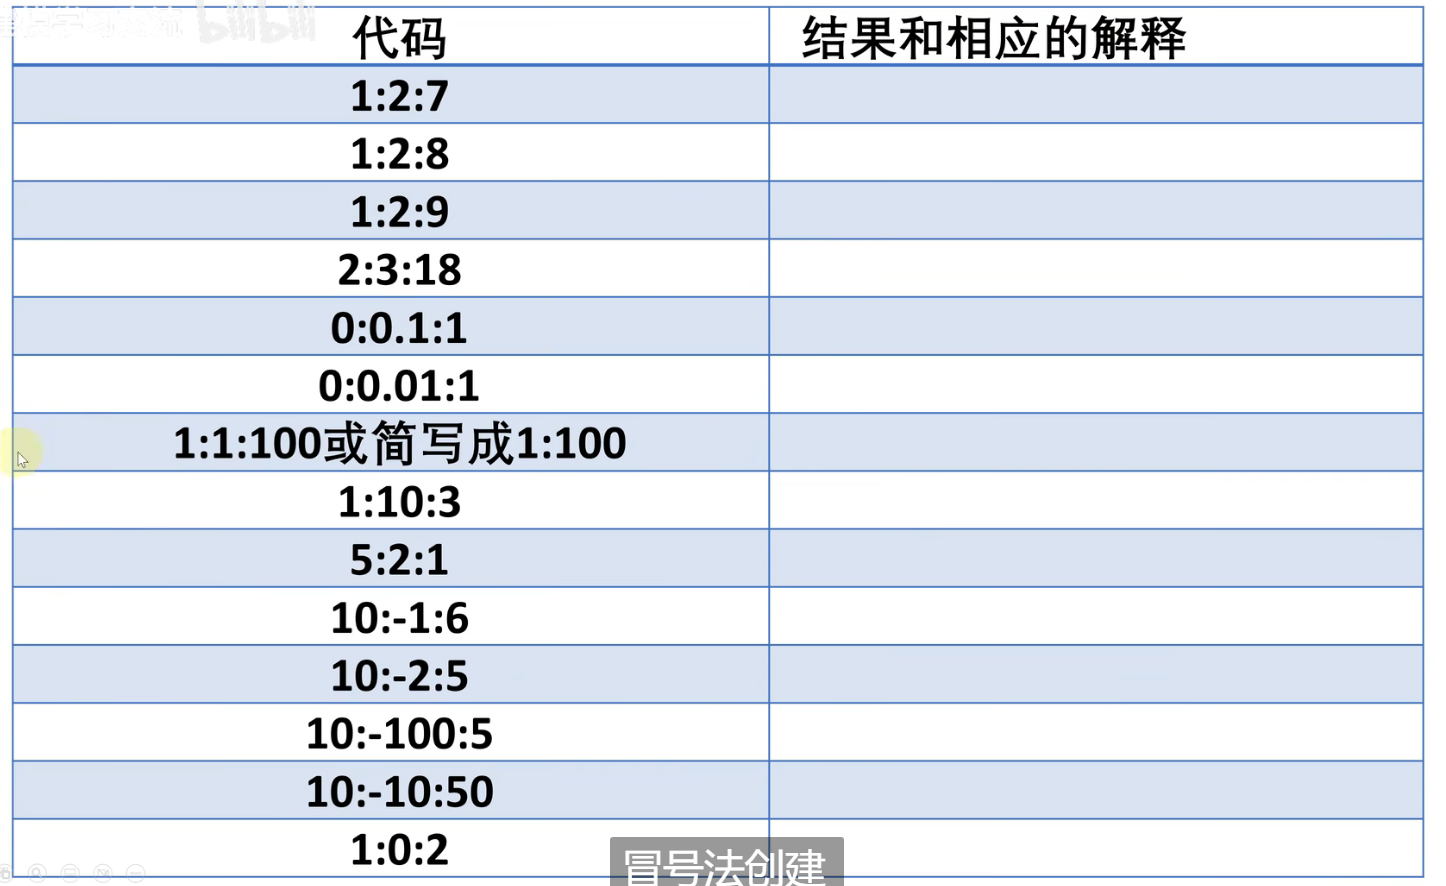

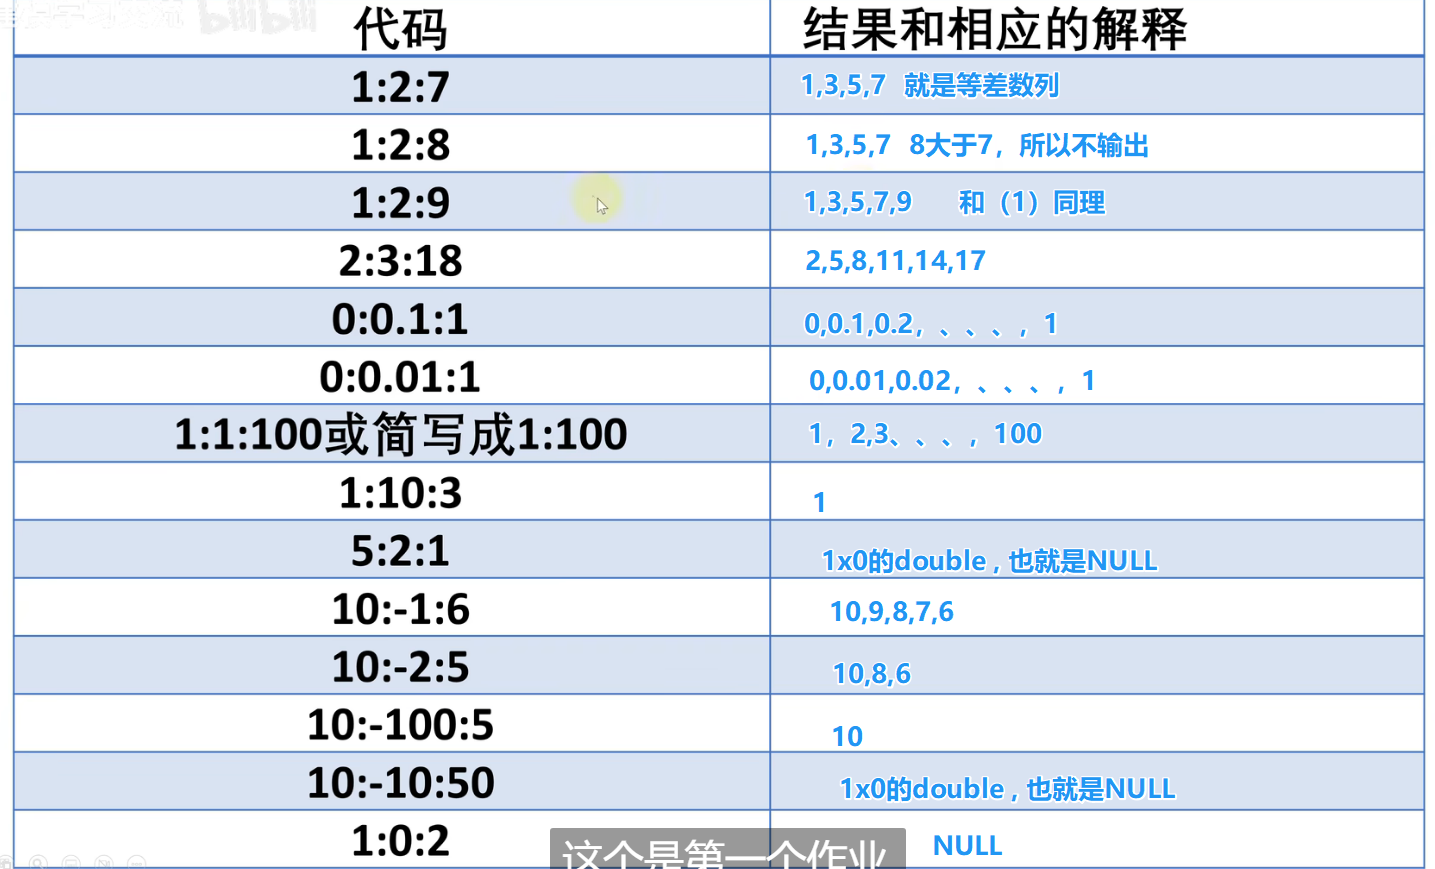

## 3.2.2 代码解释

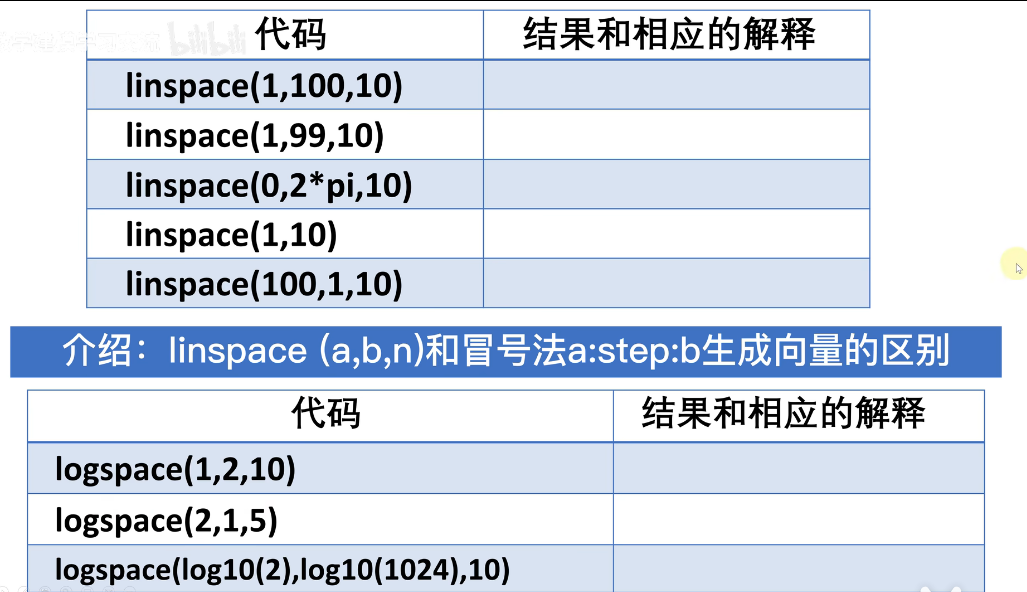

### 第一题

linspace(1,100,10)  % A到B,总差值为B-A,内部数据有n-2个,内部间隔有n-1个,所以公差为d = (B-A) / (n-1) 从1到100,等差数列,10个数

ans =      1    12    23    34    45    56    67    78    89   100


linspace(1,99,10)   % d = (99-1) / (10-1) = 98 / 9 = 11 + 8/9

ans =     1.0000   11.8889   22.7778   33.6667   44.5556   55.4444   66.3333   77.2222   88.1111   99.0000


linspace(0,2*pi,10) % d = 2*pi / 9

ans =          0    0.6981    1.3963    2.0944    2.7925    3.4907    4.1888    4.8869    5.5851    6.2832


linspace(1,10)      % 等价于n = 100,所以d = (10-1) / (100-1) = 9 / 99 = 1 / 11 

ans =     1.0000    1.0909    1.1818    1.2727    1.3636    1.4545    1.5455    1.6364    1.7273    1.8182    1.9091    2.0000    2.0909    2.1818    2.2727    2.3636    2.4545    2.5455    2.6364    2.7273    2.8182    2.9091    3.0000    3.0909    3.1818    3.2727    3.3636    3.4545    3.5455    3.6364    3.7273    3.8182    3.9091    4.0000    4.0909    4.1818    4.2727    4.3636    4.4545    4.5455    4.6364    4.7273    4.8182    4.9091    5.0000    5.0909    5.1818    5.2727    5.3636    5.4545


linspace(100,1,10)  % d = (1-100) / 9 = -11

ans =    100    89    78    67    56    45    34    23    12     1


### 第二题

logspace(1,2,10)    % 10^A * q ^ (n-1) = 10^B 

ans =    10.0000   12.9155   16.6810   21.5443   27.8256   35.9381   46.4159   59.9484   77.4264  100.0000


logspace(2,1,5)     % 

ans =   100.0000   56.2341   31.6228   17.7828   10.0000


logspace(log10(2) , log10(1024) , 10) % 想得到A-B的等比数列:log10(A) , log10(B) , n 即可

ans = 1.0e+03 *

    0.0020    0.0040    0.0080    0.0160    0.0320    0.0640    0.1280    0.2560    0.5120    1.0240


### 3.2.2 向量的引用

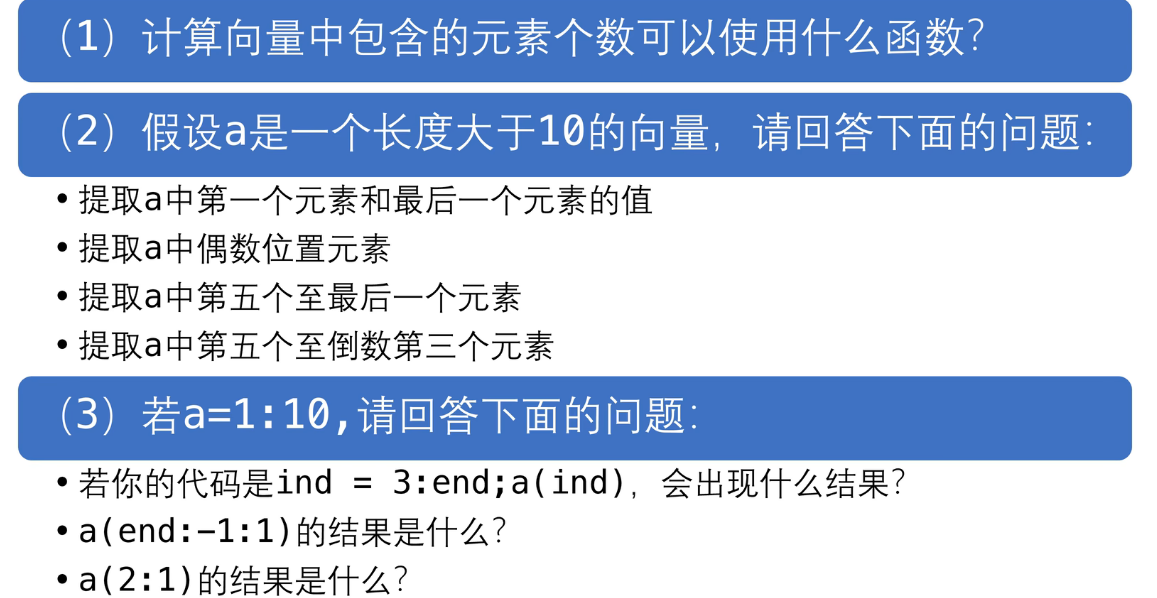

**第1题**

**ans: 使用length() or numel()**

a = 1:2:11

a =      1     3     5     7     9    11


length(a)

ans = 6

numel(a)

ans = 6

**第2题**

num = 16

num = 16

a = linspace(1,20,num)

a =     1.0000    2.2667    3.5333    4.8000    6.0667    7.3333    8.6000    9.8667   11.1333   12.4000   13.6667   14.9333   16.2000   17.4667   18.7333   20.0000


ans:

% 提取a中第一个元素和最后一个元素的值
a([1,end])

ans =      1    20


% 提取a中偶数位置元素
a(2:2:end)

ans =     2.2667    4.8000    7.3333    9.8667   12.4000   14.9333   17.4667   20.0000


% 提取a中第五个至最后一个元素
a(5:end)

ans =     6.0667    7.3333    8.6000    9.8667   11.1333   12.4000   13.6667   14.9333   16.2000   17.4667   18.7333   20.0000


% 提取a中第五个至倒数第三个元素
a(5:end-2)  % 注意这里是减2

ans =     6.0667    7.3333    8.6000    9.8667   11.1333   12.4000   13.6667   14.9333   16.2000   17.4667


**第3题**

(1) end不能放在数组外面

(2) 倒序排列

a = 1:2:8

a =      1     3     5     7


a(end : -1 : 1)

ans =      7     5     3     1


(3) NULL

a(2:1)


ans =

  空的 1×0 double 行向量



### 3-2-3 向量元素的修改和删除

1.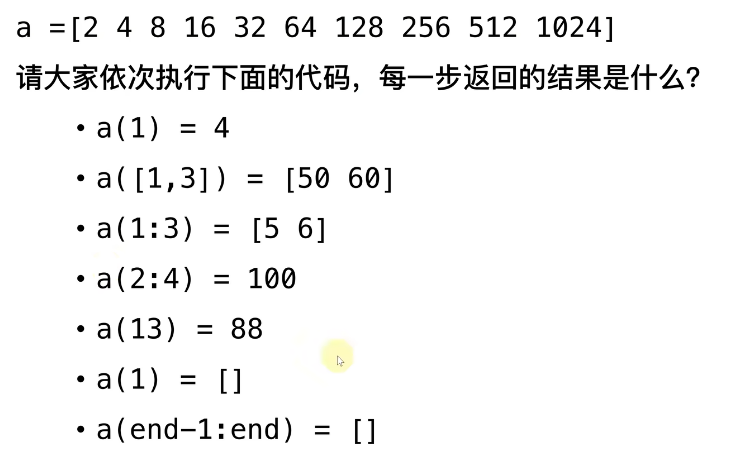

ans:

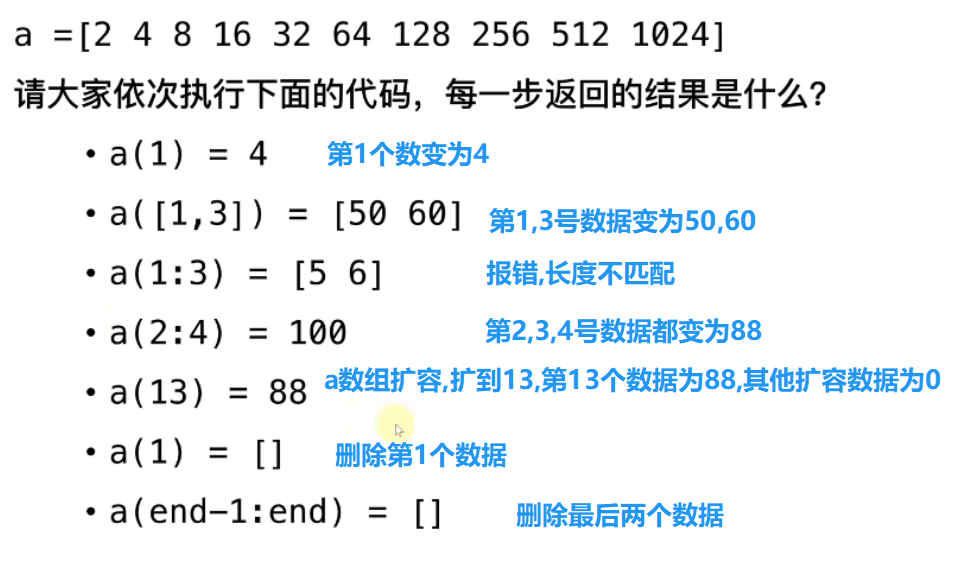

a = 1:2:9

a =      1     3     5     7     9


a(1) = 4 

a =      4     3     5     7     9


a([1,3]) = [50 60]

a =     50     3    60     7     9


% a(1:3) = [5 6]  % 无法执行赋值，因为左侧和右侧的元素数目不同。
a(13) = 88

a =     50     3    60     7     9     0     0     0     0     0     0     0    88


a(1) = []

a =      3    60     7     9     0     0     0     0     0     0     0    88


a(end - 1 : end) = []

a =      3    60     7     9     0     0     0     0     0     0


## 3.3.1 矩阵的创建方法

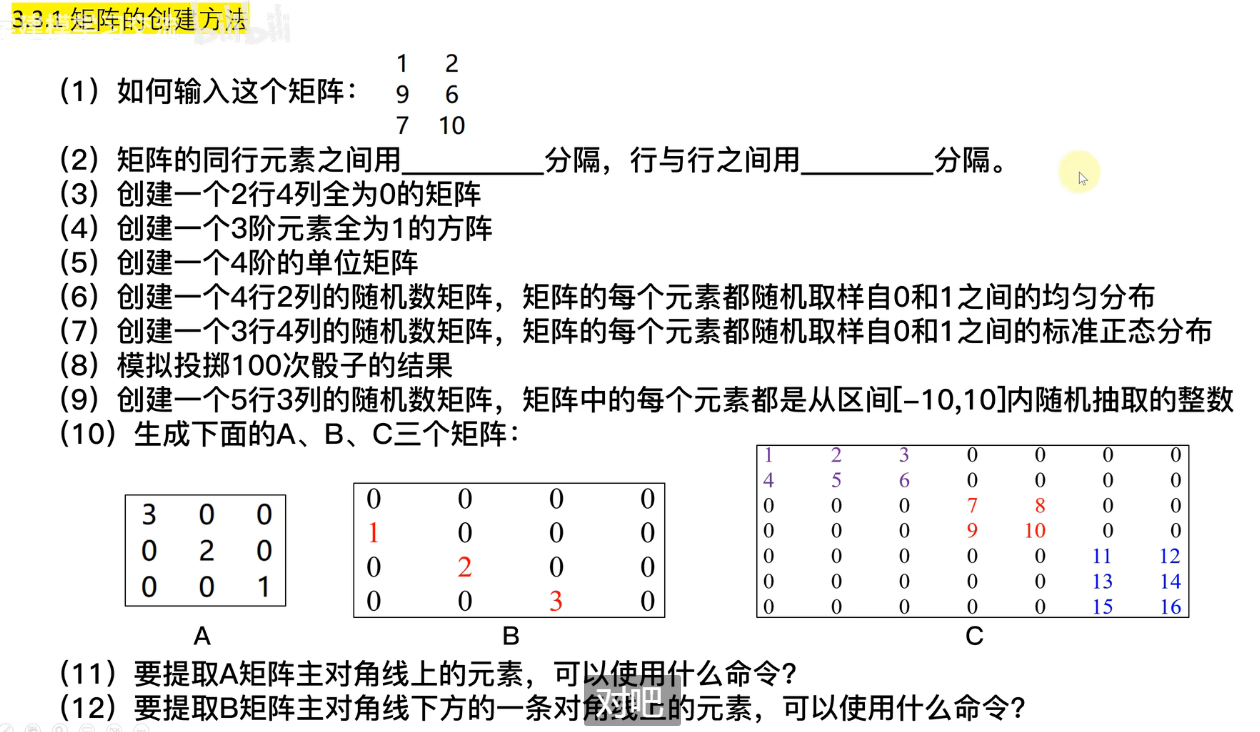

1. 

[1 2 ; 9 6 ; 7 10]

ans =      1     2
     9     6
     7    10


2. 

ans : 逗号或者空格    回车或者分号

3. 

zeros(2,4)

ans =      0     0     0     0
     0     0     0     0


4. 

ones(3)

ans =      1     1     1
     1     1     1
     1     1     1


5. 

eye(4,4)

ans =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


6. 

rand(4,2)

ans =     0.3817    0.1472
    0.9071    0.3099
    0.3036    0.4182
    0.8673    0.2102


7. 

randn(3,4)

ans =     1.0134   -0.6663    1.8944    0.6489
   -0.3330   -1.1875    1.3384    1.6839
    1.2386    0.6070    1.0753    1.3734


8. 

% 定义采样总数
total_num = 1000;
% 创建一个1x6的0向量,存储1-6出现的次数
result = zeros(1,6) ;  
% 创建收集骰子点数出现频率的向量
data = randi([1,6] , 1 , total_num);
% 开始计数
for x = 1:total_num
    result(data(x)) = result(data(x)) + 1 ;
end
% 得到结果
result

result =    176   178   163   149   162   172


9. 

randi([-10,10],5,3)

ans =      7   -10     1
    -2     3     6
    -2    -5     1
     1     2    -4
    -1    -3    -1


10. 

diag([3 2 1] , 0)

ans =      3     0     0
     0     2     0
     0     0     1


diag([1 2 3] , -1)

ans =      0     0     0     0
     1     0     0     0
     0     2     0     0
     0     0     3     0


A1 = [1 2 3 ; 4 5 6];
A2 = [7 8 ; 9 10];
A3 = [11 12 ; 13 14 ; 15 16];
A = blkdiag(A1 , A2 , A3)

A =      1     2     3     0     0     0     0
     4     5     6     0     0     0     0
     0     0     0     7     8     0     0
     0     0     0     9    10     0     0
     0     0     0     0     0    11    12
     0     0     0     0     0    13    14
     0     0     0     0     0    15    16


11. 

diag(A , 0)

ans =      1
     5
     0
     9
     0
    13
    16


12.

diag(A , -1)

ans =      4
     0
     0
     0
     0
    15


### 3.3.2 矩阵元素的引用

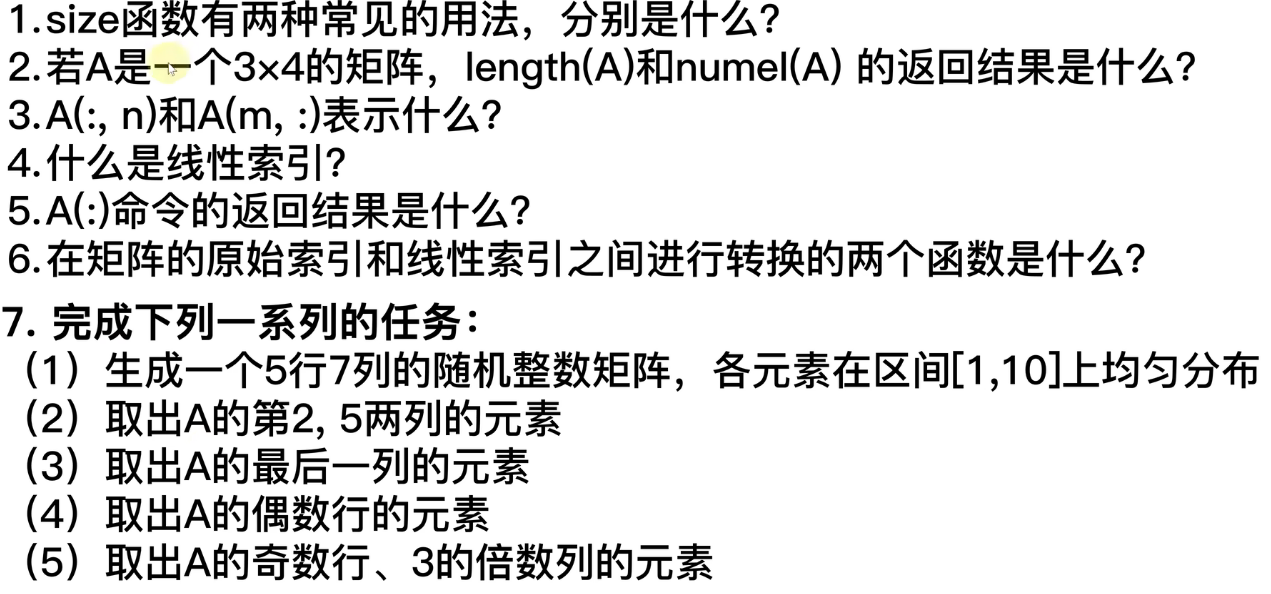

1. 

①size(A)得到[ row , col ]

②size(A,n) 得到n = 1 : row  n = 2 : col

2. 

(1) 4(length返回大的行列数)

(2) 12(numel返回总数)

3. 

(1) 选择A的第n列

(2) 选择A的第m行

4. 

MATLAB内部对于矩阵的存储方式

5. 

A矩阵的线性索引列向量

6. 

sub2ind

ind2sub

7. 

% 生成一个5行7列的随机整数矩阵，各元素在区间[1，10]上均匀分布
A = randi([1,10] , 5 , 7)

A =      4     9     7     4     7     1     5
     6     4     5     7     7     7     3
     4     8     9     1     5     2     7
     7    10     7     1     6     6     6
     1     6     6     9     2     1     7


% 取出A的第2，5两列的元素
A(: , [2 , 5])

ans =      9     7
     4     7
     8     5
    10     6
     6     2


% 取出A的最后一列的元素
A(:,end)

ans =      5
     3
     7
     6
     7


% 取出A的偶数行的元素
A(2:2:end , :)

ans =      6     4     5     7     7     7     3
     7    10     7     1     6     6     6


% 取出A的奇数行、3的倍数列的元素
A(1:2:end , 3:3:end)

ans =      7     1
     9     2
     6     1


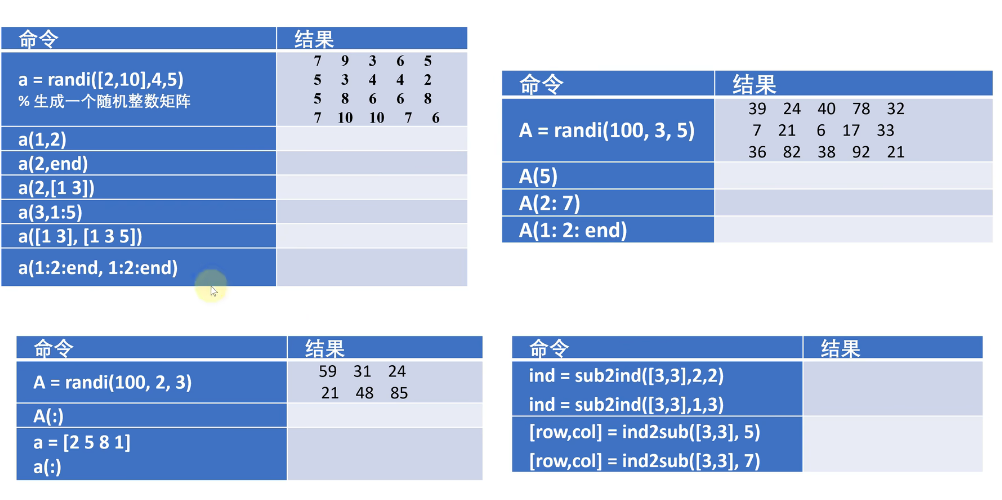

略